# Sistemas Realimentados - 2023/2

## Nome: Luiza Batista Laquini

## Data limite para entrega: 8/11, 6h

**Importante lembrar:**

- Entrega após a data/horário acima: a nota será multiplicada por $1-e^{-30/h}$, onde h são as horas em atraso (Exemplo: 24h, multiplica por 0.71).

- Não é recebido por email

- Cabe a vocês garantir que o documento entregue é um arquivo pdf legível, e que não foi entregue com erro. Para isto, basta depositar e abrir para conferir.

- Código é apenas uma informação complementar, e não é considerada parte da solução para fins de avaliação.

- Caso não haja tempo de fazer todo o trabalho, entreguem no prazo o que estiver pronto.

## Trabalho 4 - Análise da resposta em frequência

I=21; % Seu valor de I
[nyq1,nyq2]=ini_t4(I);
datetime('now')

ans = datetime
   08-Nov-2023 03:06:29


## Atividade 1: Análise de gráficos de Bode

O gráfico de Bode abaixo contém ganhos, polos e zeros, todos afastados de pelo menos uma década.

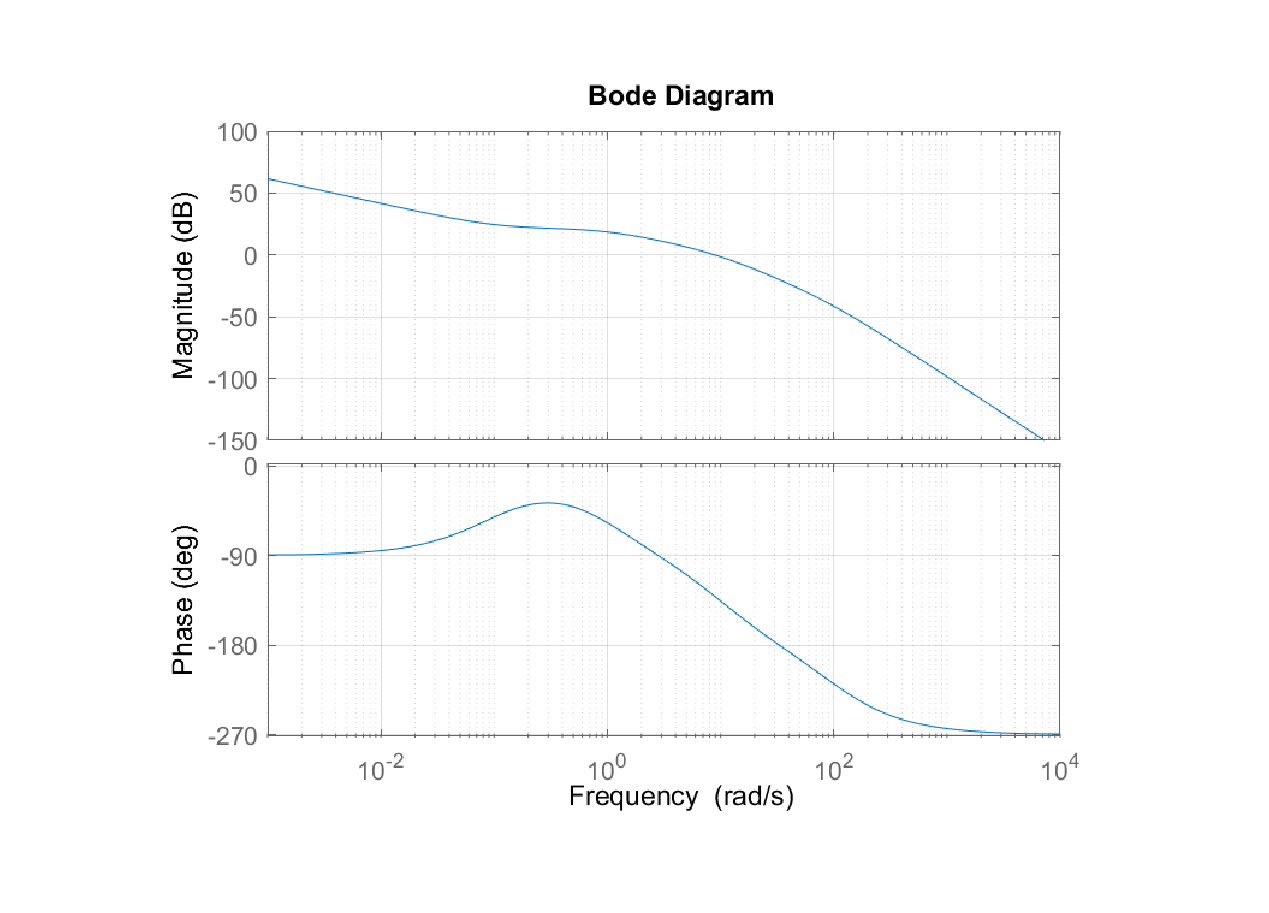

figure
imshow('fig1.png');

1.1 Obtenha a função de transferência no formato $G(s)=K\frac{(1+sz_1)(1+sz_2)...}{(1+sp_1)(1+sp_2)...}$ e refaça o gráfico de Bode para verificar se está igual ao fornecido.

Fazendo uma análise por década do gráfico de Bode fornecido:

- Inicialmente, na frequência 10^-3, a fase está em -90 e o módulo decresce a 20dB por década, indicando um polo na origem.

- Na frequência 10^-2 o efeito do polo na origem se mantém.

- Na frequência 10^-1 temos a fase aumentando e o módulo se mantendo estável, o que indica a presença de um zero somando 20db por década que anula o efeito do polo na origem.

- Já na frequência 10^0 a fase volta a cair e o módulo também (a 20dB/dec) indicando a presença de outro polo nessa frequência.

- A seguir, em 10^1, a fase continua a cair e o módulo também, entretanto este passa a cair mais rápidamente (a 40/dB/dec), indicando a presença de outro polo nessa frequência.

- Por fim, em 10^2, a fase continua a cair e o módulo também, entretanto este passa a cair ainda mais rápidamente (a 60/dB/dec), indicando a presença de outro polo nessa frequência.

Dada a análise, podemos agora obter a função de transferência G:

p1=0;
z1=0.1;
p2=1;
p3=10;
p4=100;

d1=conv([1 p1],[1 p2]);
d2=conv([1 p3],[1 p4]);
d=conv(d1,d2);

G=tf([1 z1],d)

G =
 
               s + 0.1
  ---------------------------------
  s^4 + 111 s^3 + 1110 s^2 + 1000 s
 
Continuous-time transfer function.
Model Properties


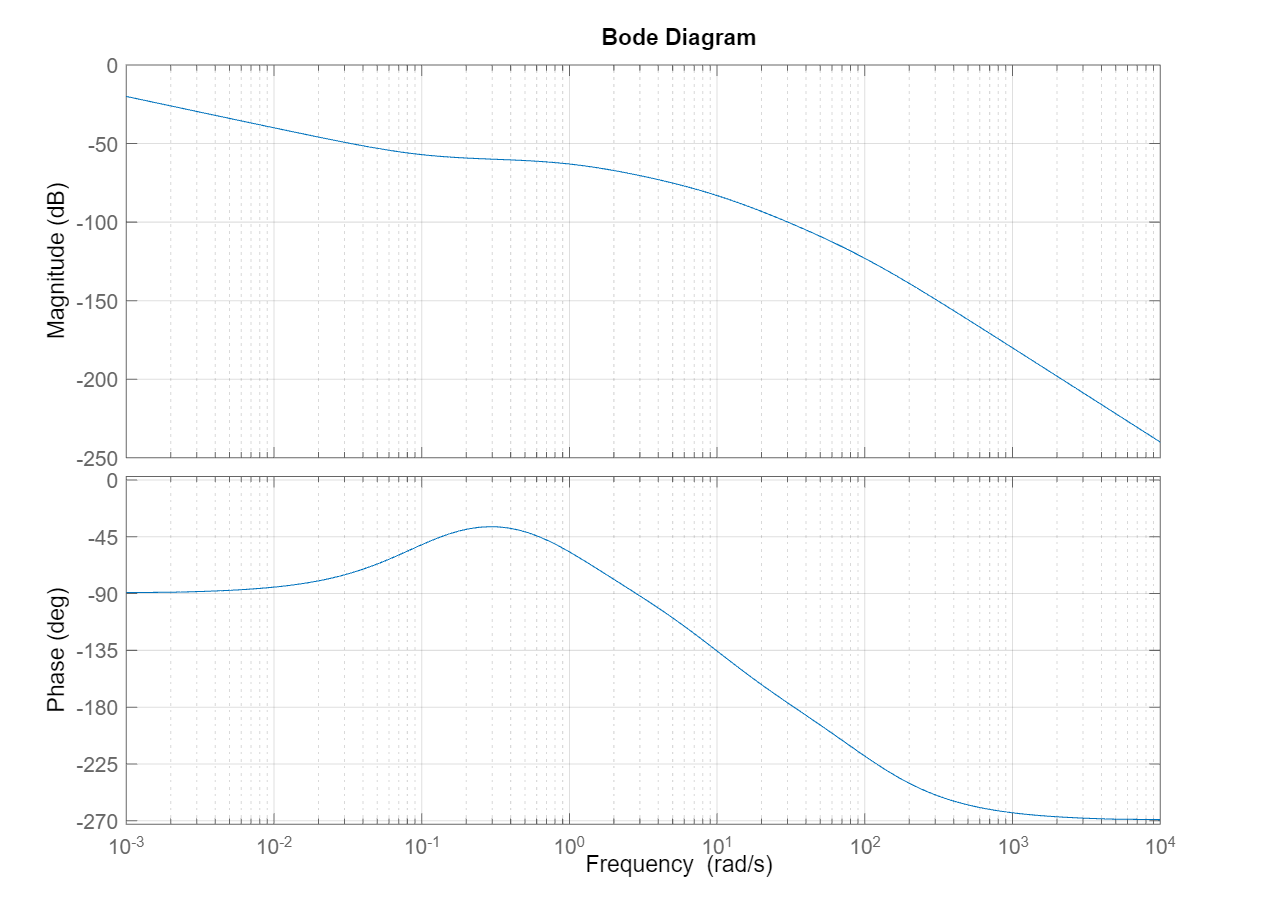

bode(G);grid;

Entretanto, como se pode observar a partir do gráfico de Bode exibido, essa G não ainda não resulta em um gráfico de Bode igual ao fornecido (os módulos se diferem bastante), pois ainda não encontramos o ganho K associado.

Devemos, portanto, encontrar esse ganho que, ao multiplicar nossa G, resulte no gráfico de Bode da Figura 1 dada.

Ao analisar a Figura 1 inferimos que para baixas frequências, nenhum outro polo ou zero possui influência no gráfico, sendo esse efeito totalmente ditado pelo ganho K e pelo polo na origem. 

Fazendo uma aproximação na frequência $4\ldotp {10}^{-3} =0\ldotp 004\mathrm{rad}/s$, temos um módulo de 50dB. A partir dele conseguimos obter o nosso ganho K:

freq = 0.004;
mag_dB=50;
mag=10^(mag_dB/20) % convertendo

mag = 316.2278

K = ((mag*freq*(freq+p2)*(freq+p3)*(freq+p4)))/(freq+z1)

K = 1.2217e+04

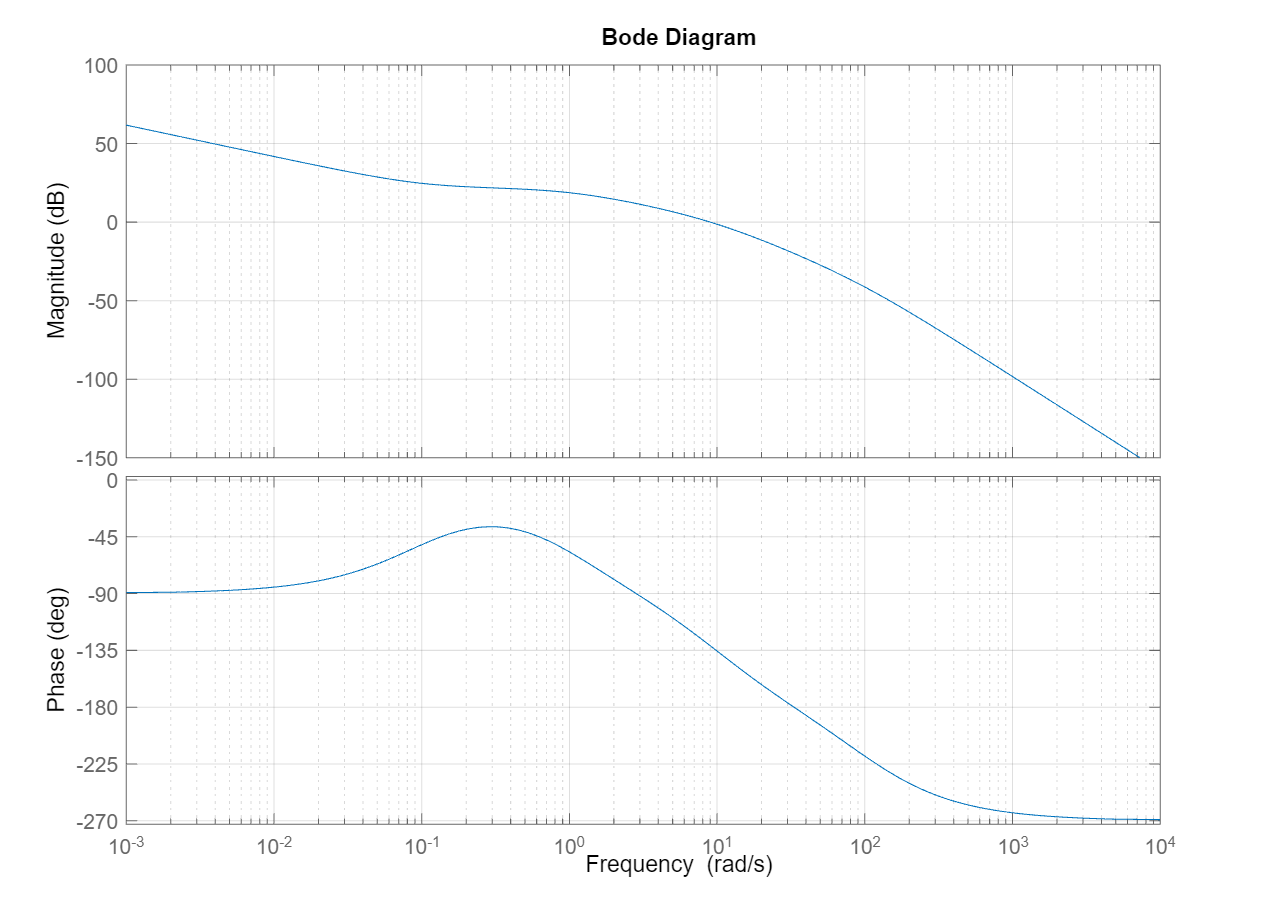

bode(K*G);grid;

A partir da multiplicação da nossa G com o ganho K encontrado (1.2217*10^4), o gráfico de Bode se iguala ao fornecido.

1.2 Obtenha as margens de fase e de ganho.

Para obter a margem de fase, tomamos a frequência de cruzamento de ganho (onde corta o módulo em 0dB) e avaliamos qual a fase nessa frequência, que, olhando a figura, está em aproximadamente -130º. A margem de fase é a distância em graus até -180º. Logo, MF = 50º, aproximadamente.

Para obter a margem de ganho, tomamos a frequência de cruzamento de fase (onde corta a fase em -180º) e avaliamos qual o módulo nessa frequência, que, olhando a figura, vemos que está em aproximadamente -20dB. A margem de ganho é a distância em graus até 0dB. Logo, MG = 20dB, aproximadamente.

Podemos usar a nossa G obtida que se iguala à imagem fornecida para conferir esses valores via código:

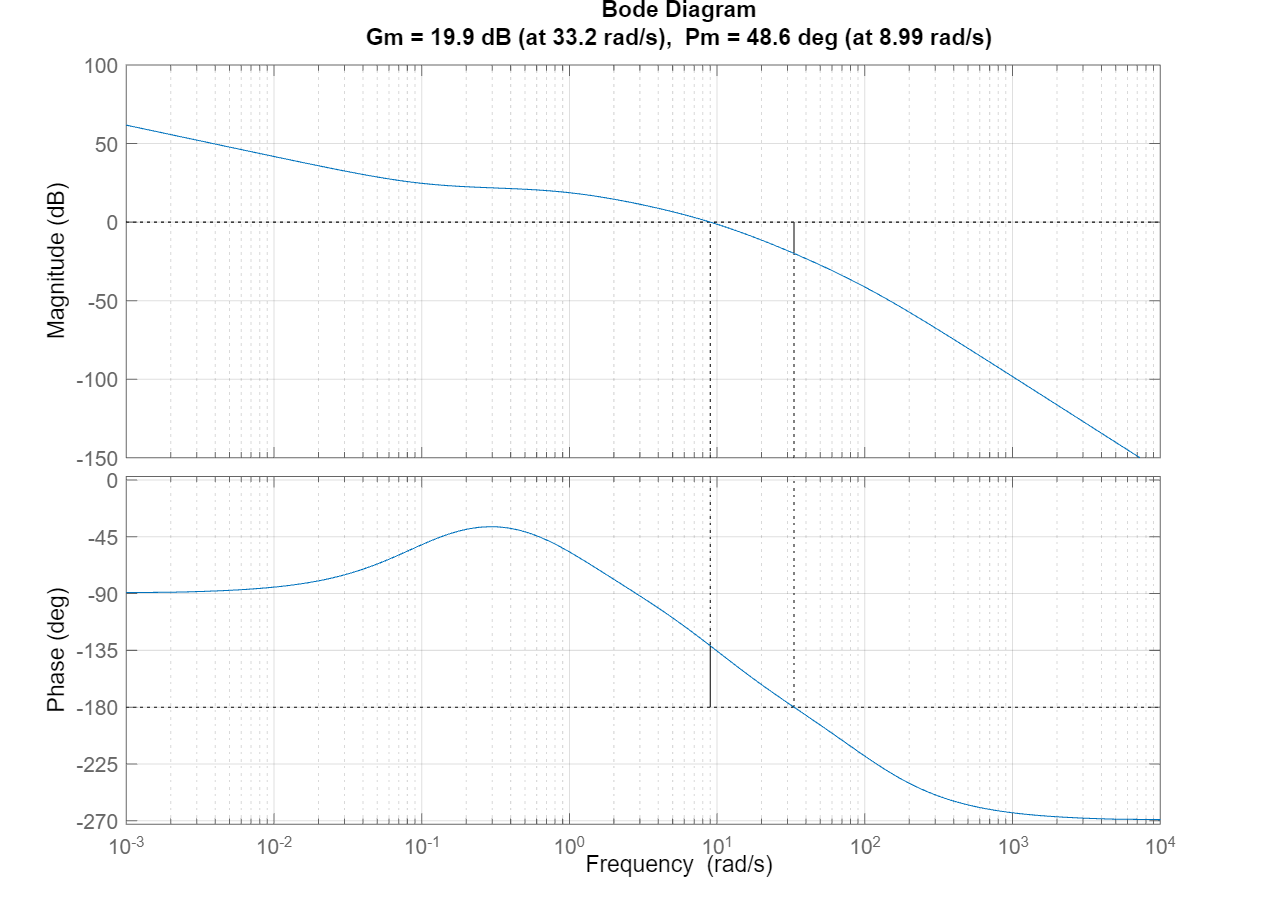

margin(K*G);grid;

Os valores se aproximam.

## Atividade 2: Critério de Nyquist

Seja o gráfico de Nyquist abaixo de $G(s)=\frac{K}{s(s+a)(s+b)}$, $a>0, b>0$. desenhado com $K=1.$

nyq1

nyq1 = -2.4000

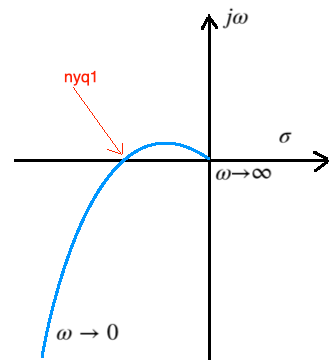

2.1 Obtenha as condições para estabilidade usando o critério simplificado de Nyquist. Escreva aqui, ou faça à mão, digitalize e coloque aqui como figura (imshow). 

O critério simplificado de Nyquist é dado por:


$$\phi=(Z_d-P_d-\frac{P_\omega}{2}).180º$$


Onde:

$\phi:$ângulo feito pelo gráfico polar em torno do ponto -1 quando $\omega$ varia de infinito a zero.

$P_d:$polos de G(s) no semi-plano direito 

$P_\omega:$polos de G(s) na origem

$Z_d:$polos de malha fechada no semi-plano direito ( é o que se quer saber)

Os 3 primeiros ($\phi,P_d,P_\omega$) são dados de malha aberta, enquanto $Z_d$ é um dado de malha fechada.

Para estabilidade, $\phi$ deve ser negativo ($Z_d=0$).

Podemos extrair diretamente da G(s), os dados de malha aberta. Observa-se que há um polo na origem, portanto, $P_\omega = \frac12$. E dado que a>0 e b>0, então não há polos no SPD. Portanto, $P_d = 0$. 

Para a estabilidade, não podemos ter zeros nos SPD. Portanto, fazemos $Z_d = 0$. Assim, podemos calcular o valor de $\phi$:


$$\phi=(0 - 0 - \frac12).180º$$



$$\phi=-90º$$


Sendo nyq1 = -2.4, o ponto -1 do fasor está "dentro" da curva da figura, de forma que o fasor varie de 0 a -90º passando por "fora". Assim, para esse gráfico de nyquist $\phi=270º$ e o sistema é instável, pois para a estabilidade $\phi$ deveria ser -90º.

2.2 Obtenha os valores de $K\in[-\infty, \infty]$ para que esse sistema seja estável, esboçando o gráfico de Nyquist para K negativo.

Para que o sistema seja estável já sabemos que precisamos de $\phi=-90º$. Para que isso seja alcançado, o -1 deve estar localizado à esquerda da curva do gráfico. Isso significa dizer que o valor de nyq1 deve ser maior que -1. 

Multiplicar nyq1 por um ganho faz o ponto passar à esquerda do -1, ficando estável.


$$|K\ldotp \mathrm{nyq1}|<|1|$$



$$K<|\frac{1}{\mathrm{nyq1}}|$$



$$K<|\frac{1}{-2\ldotp 4}|$$


$K<$ 0.4167

Portanto, para $K<$ 0.4167, temos a variação do ângulo como sendo -90º onde o critério de nyquist é atendido.

Esboçando o gráfico de Nyquist para K negativo (basta espelharmos na origem, que é o equivalente a adiconar 180º) - não altera nosso K:

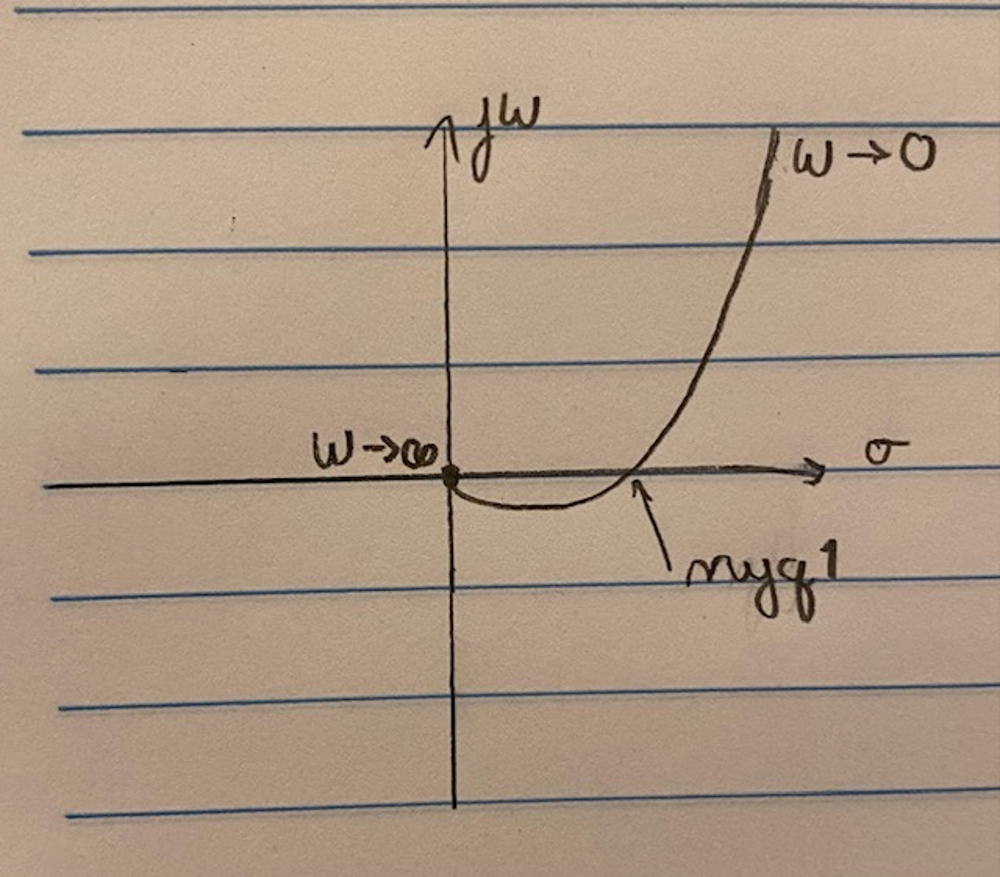

Seja agora o gráfico de $G(s)=\frac{K(s+a)^2}{s^3}$, $a>0$, desenhado com $K=1.$

nyq2

nyq2 = -0.2000

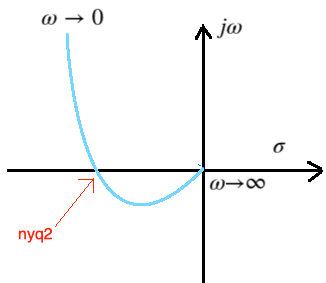

2.3 Obtenha as condições para estabilidade usando o critério simplificado de Nyquist. Escreva aqui, ou faça à mão, digitalize e coloque aqui como figura. 

Podemos extrair diretamente da G(s), os dados de malha aberta. Observa-se que há três polos na origem, portanto, $P_\omega = \frac32$. Não há zeros no SPD, portanto, $P_d = 0$. 

Para a estabilidade, não podemos ter zeros nos SPD. Portanto, fazemos $Z_d = 0$. Assim, podemos calcular o valor de $\phi$:


$$\phi=(0 - 0 - \frac32).180º$$



$$\phi=-270º$$


Sendo nyq2 = -0.2, o ponto -1 do fasor está à esquerda da curva da figura. Assim, para esse gráfico de nyquist $\phi=90º$ e o sistema é instável, pois para a estabilidade $\phi$ deveria ser -270º.

2.4 Obtenha os valores de $K\in[-\infty, \infty]$ para que esse sistema seja estável.

Para que o sistema seja estável já sabemos que precisamos de $\phi=-270º$. Para que isso seja alcançado, o -1 deve envolver a curva do gráfico, estando "dentro" dele. Isso significa dizer que o valor de nyq2 deve ser menor que -1. 

Multiplicar nyq2 por um ganho faz a curva envolver o -1, ficando estável.


$$|K\ldotp \mathrm{nyq2}|>|1|$$



$$K>|\frac{1}{\mathrm{nyq2}}|$$



$$K>|\frac{1}{-0\ldotp 2}|$$



$$K>5$$


Portanto, para $K>5$, temos a variação do ângulo como sendo -270º onde o critério de nyquist é atendido.

## Atividade 3: Efeito do ganho na estabilidade relativa.  

3.1 Use o método do lugar das raízes para ver o efeito do ganho nas margens de fase e ganho usando G1 da atividade 1, comparando o efeito do ganho sobre o amortecimento e sobre a margem de fase. Dica: rltool permite ver o LR (amortecimento) e gráfico de Bode (Margens).

Primeiro, vamos visualizar a G1 e o Lugar das Raízes correspondente para ela:

G1=K*G

G1 =
 
          1.222e04 s + 1222
  ---------------------------------
  s^4 + 111 s^3 + 1110 s^2 + 1000 s
 
Continuous-time transfer function.
Model Properties


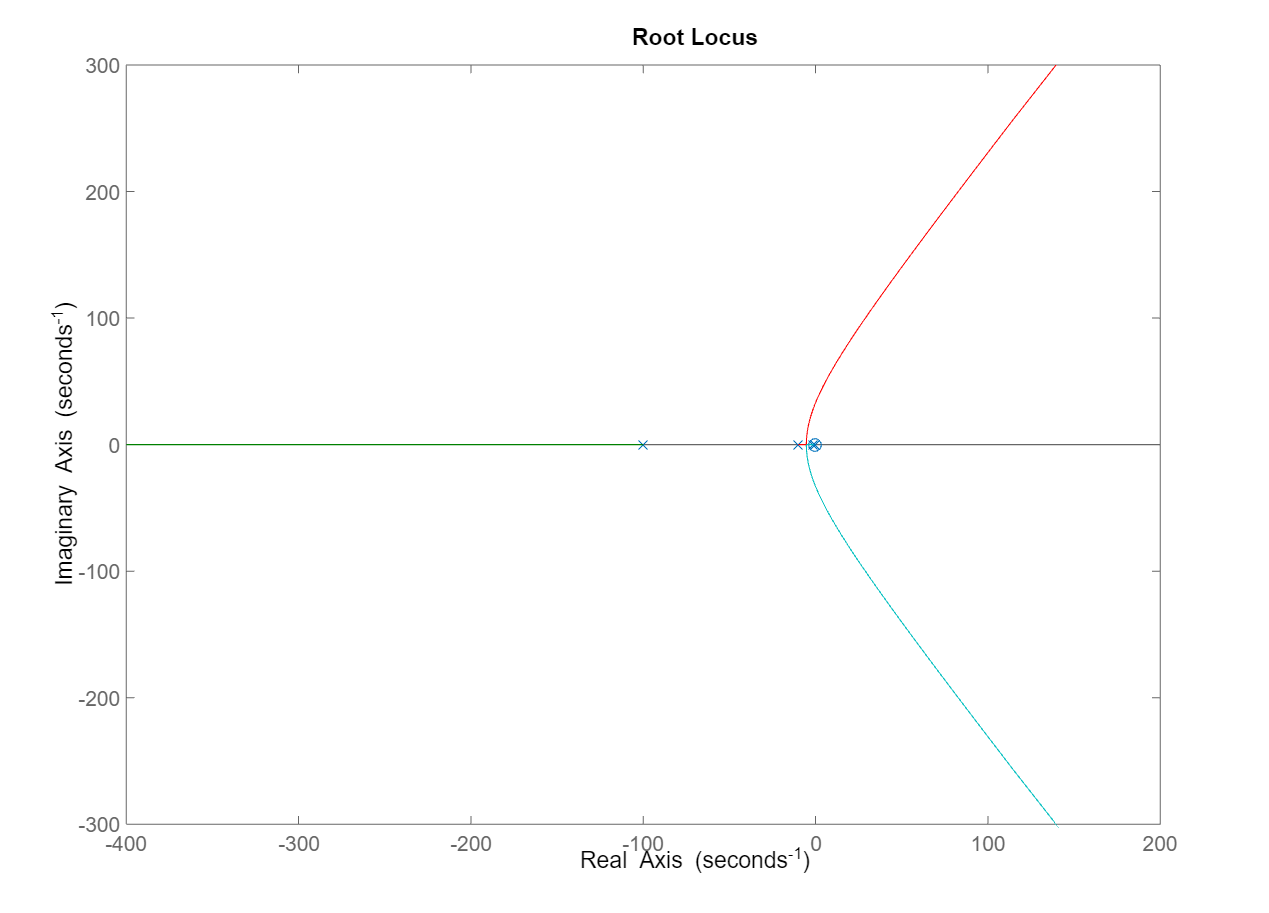

rlocus(G1)

%rltool(G1)

Vamos observar algumas variações antes de se tirar as conclusões:

Para um ganho K=0.001, temos MG=79.9dB, MF=90.6º e $\zeta = 1$ (sobre o eixo real).

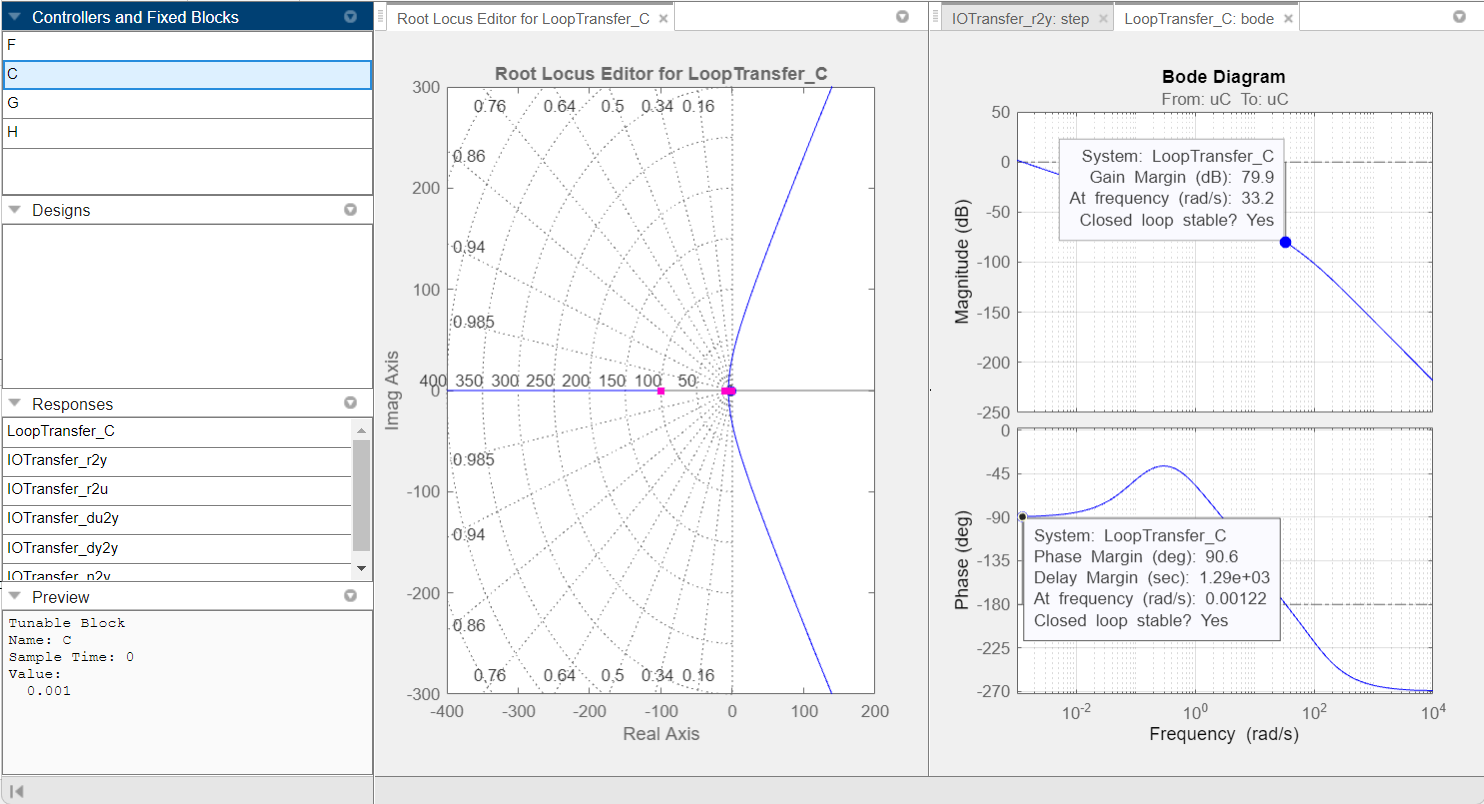

Para um ganho K=0.055343, temos MG=45.1dB, MF=127º e $\zeta = 1$ (sobre o eixo real).

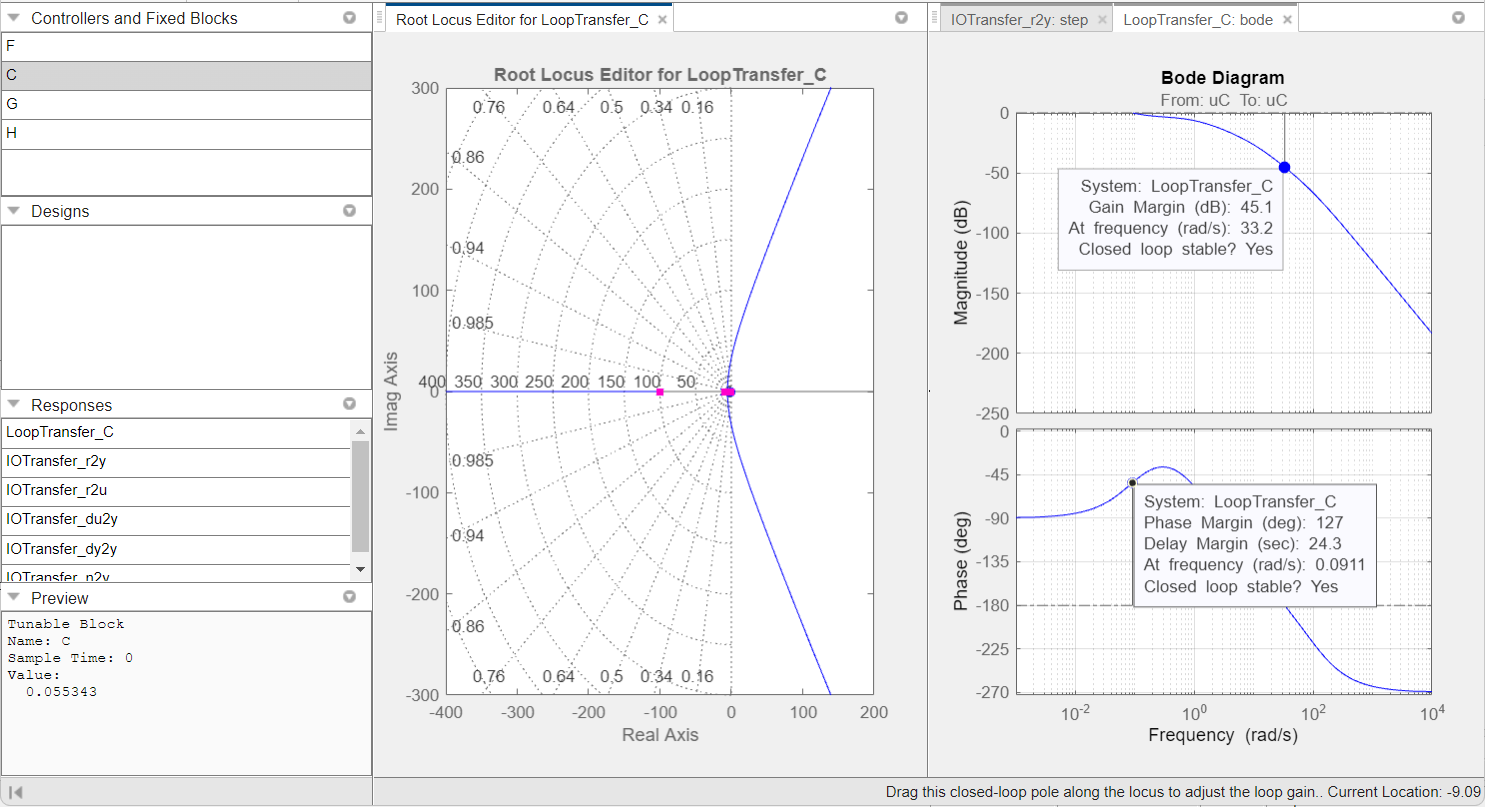

Para um ganho K=0.11823, temos MG=38.5dB, MF=122º e $\zeta = 1$ (sobre o eixo real).

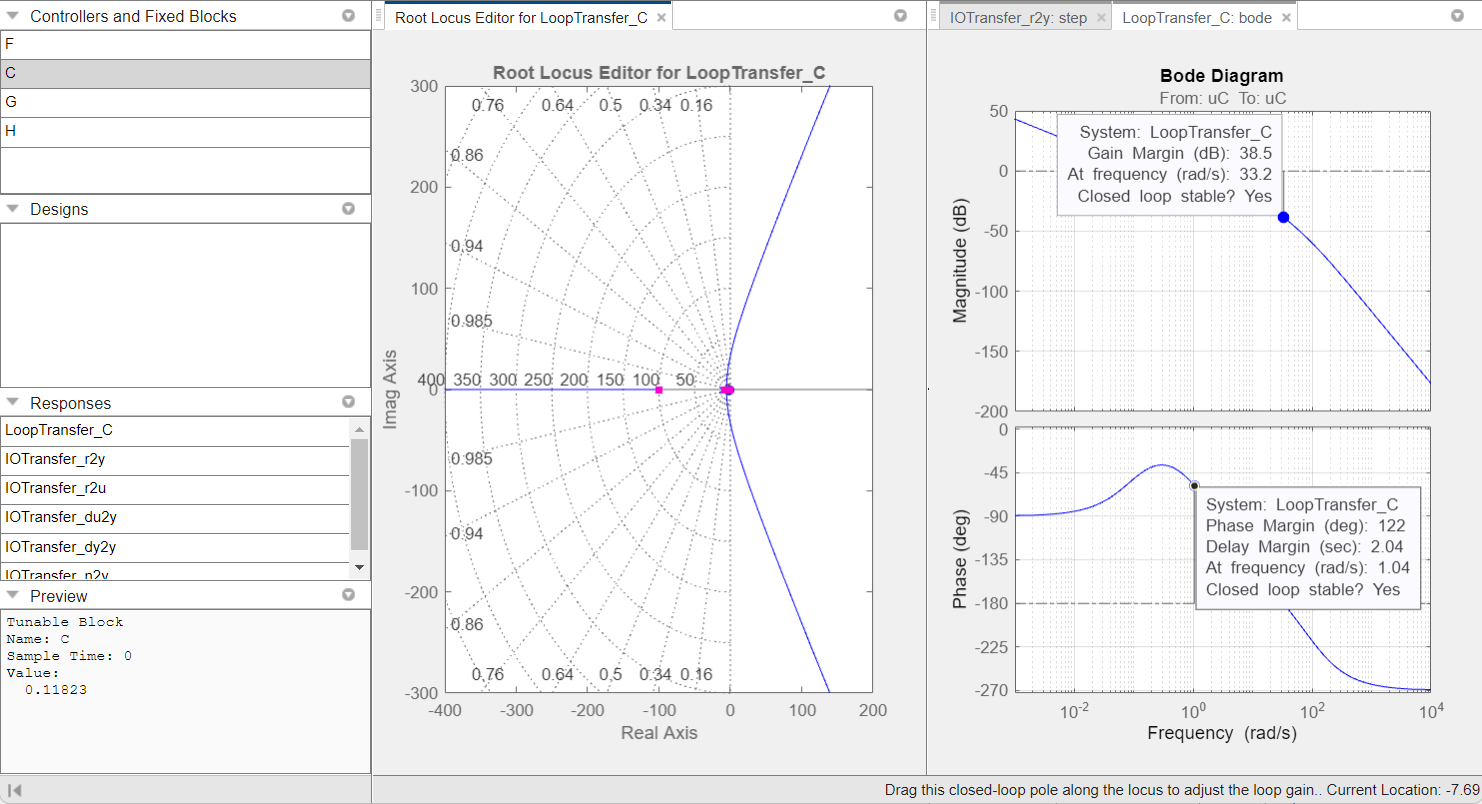

Para um ganho K=2.4764, temos MG=12dB, MF=26.4º e $\zeta = 0.222$ ("damping").

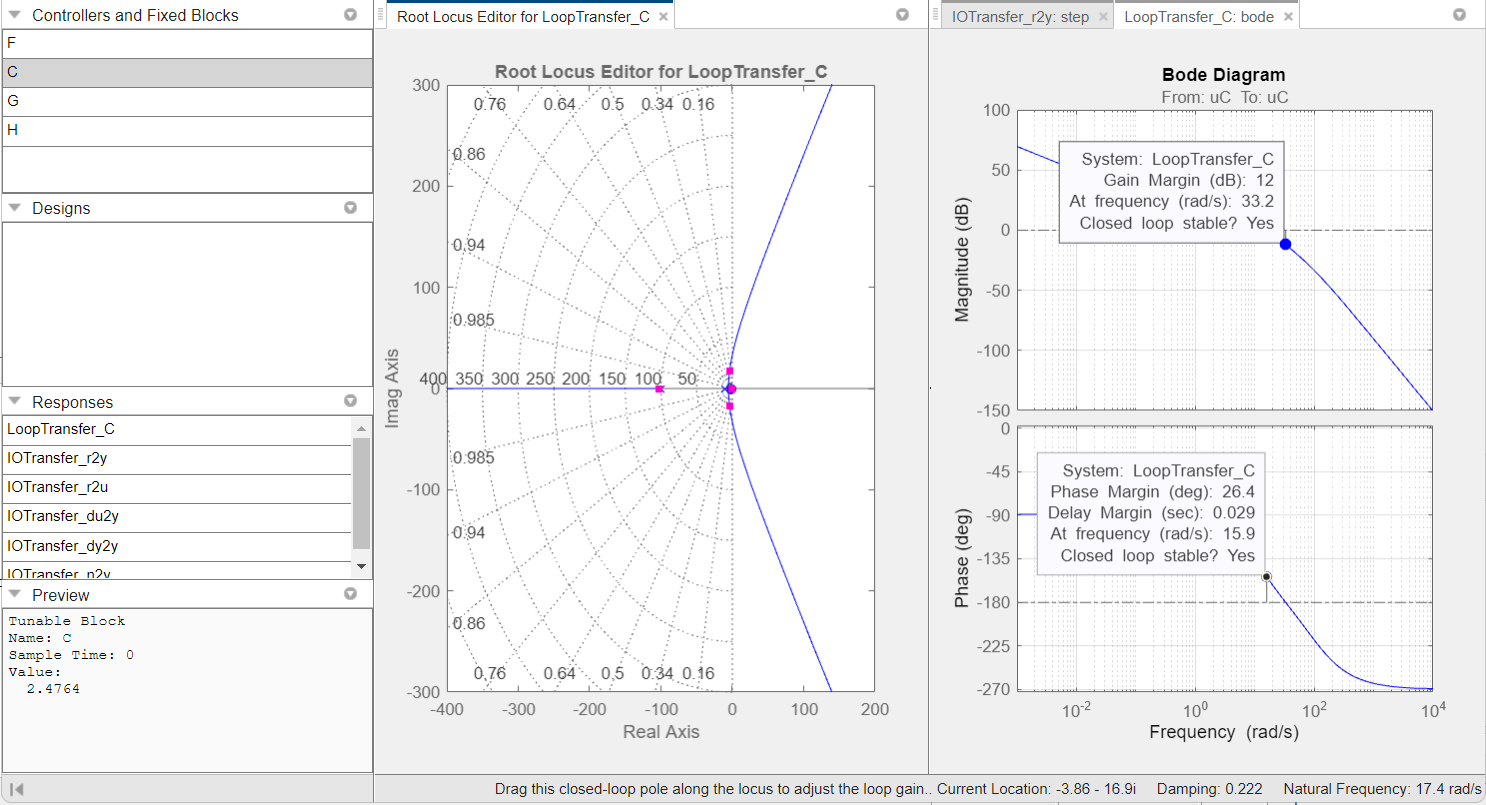

Para um ganho K=103.21, temos MG=-20.4dB, MF=-37.1º e $\zeta = -0.25$ ("damping").

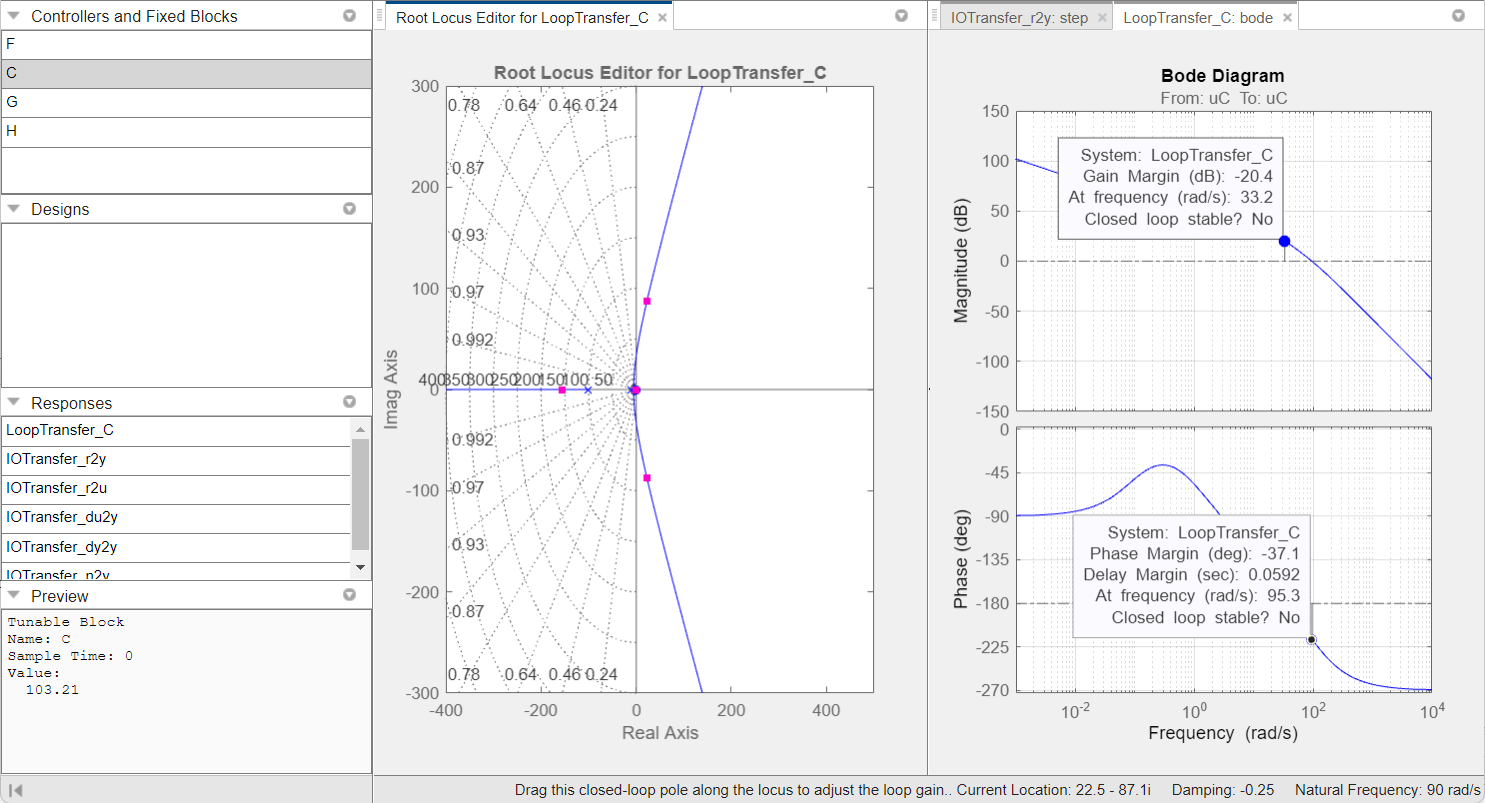

Conclusões:

- À medida que o ganho aumenta, o amortecimento diminui, o que faz total sentido já que aumentar o ganho é tornar o sistema mais rápido e, consequentemente mais oscilatório (menos amortecido).

- À medida que o ganho aumenta, a margem de ganho diminui, o que é lógico e é ilustrado pelo gráfico do ganho.

- À medida que o ganho aumenta, a margem de fase primeiro aumenta e depois diminui, o que faz total sentido porque é o que ilustra o gráfico de fase.

3.2 Escolha um ganho K tal que a margem de fase seja aproximadamente 10 graus, mostrando o LR e o gráfico de Bode para este ganho K. Qual a margem de ganho ?

Conforme pedido:

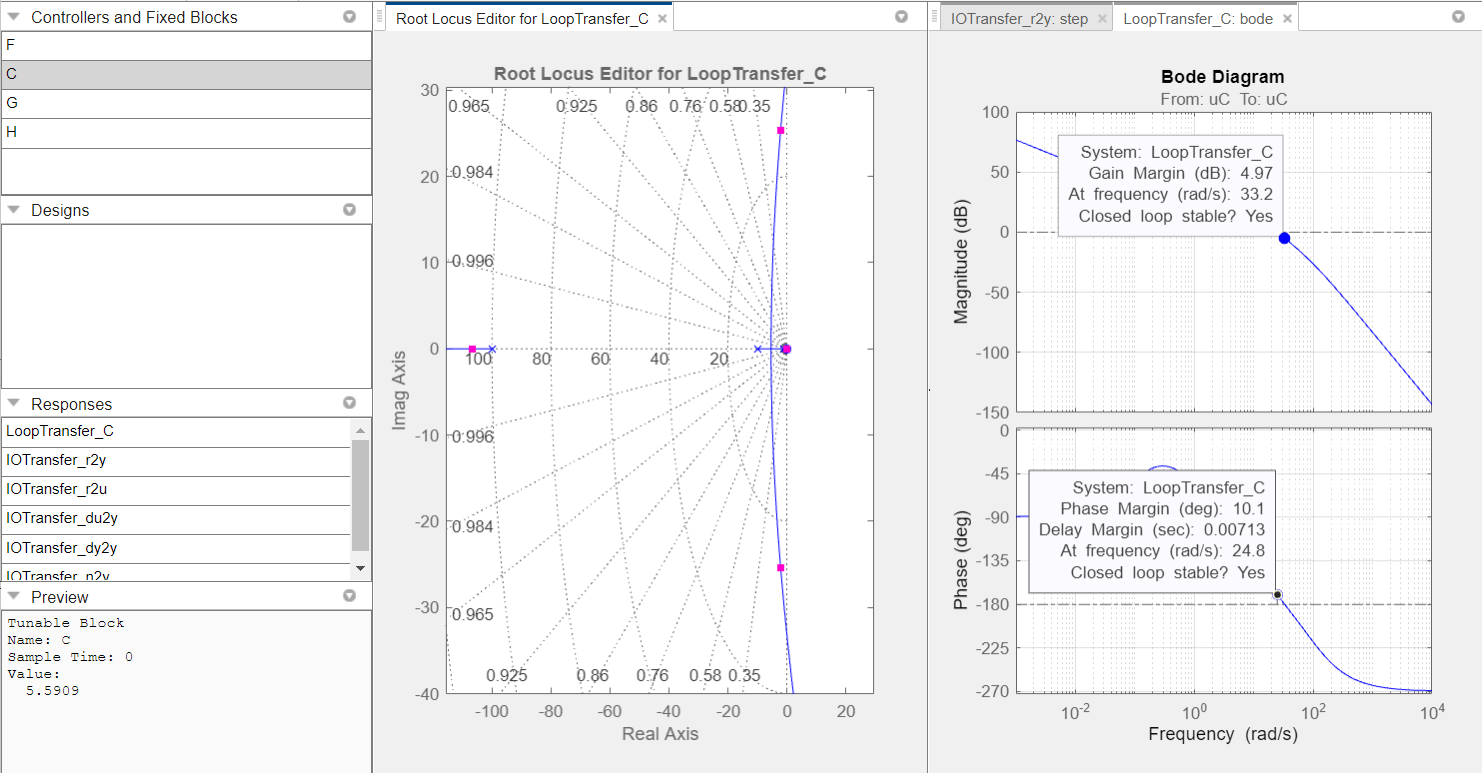

O ganho é de aproximadamente 5.5909, a margem de ganho é de 4.97dB.

## Atividade 4: Efeito de um atraso de tempo na estabilidade relativa. 

4.1 Obtenha o atraso de tempo tal que G1 com este atraso tenha margem de fase nula.  Plote então o gráfico de Bode de G1 com e sem o atraso, verificando a margem de fase e de ganho nos dois casos.

G1

G1 =
 
          1.222e04 s + 1222
  ---------------------------------
  s^4 + 111 s^3 + 1110 s^2 + 1000 s
 
Continuous-time transfer function.
Model Properties


Plotando o gráfico de Bode sem o atraso e verificando a MG e a MF:

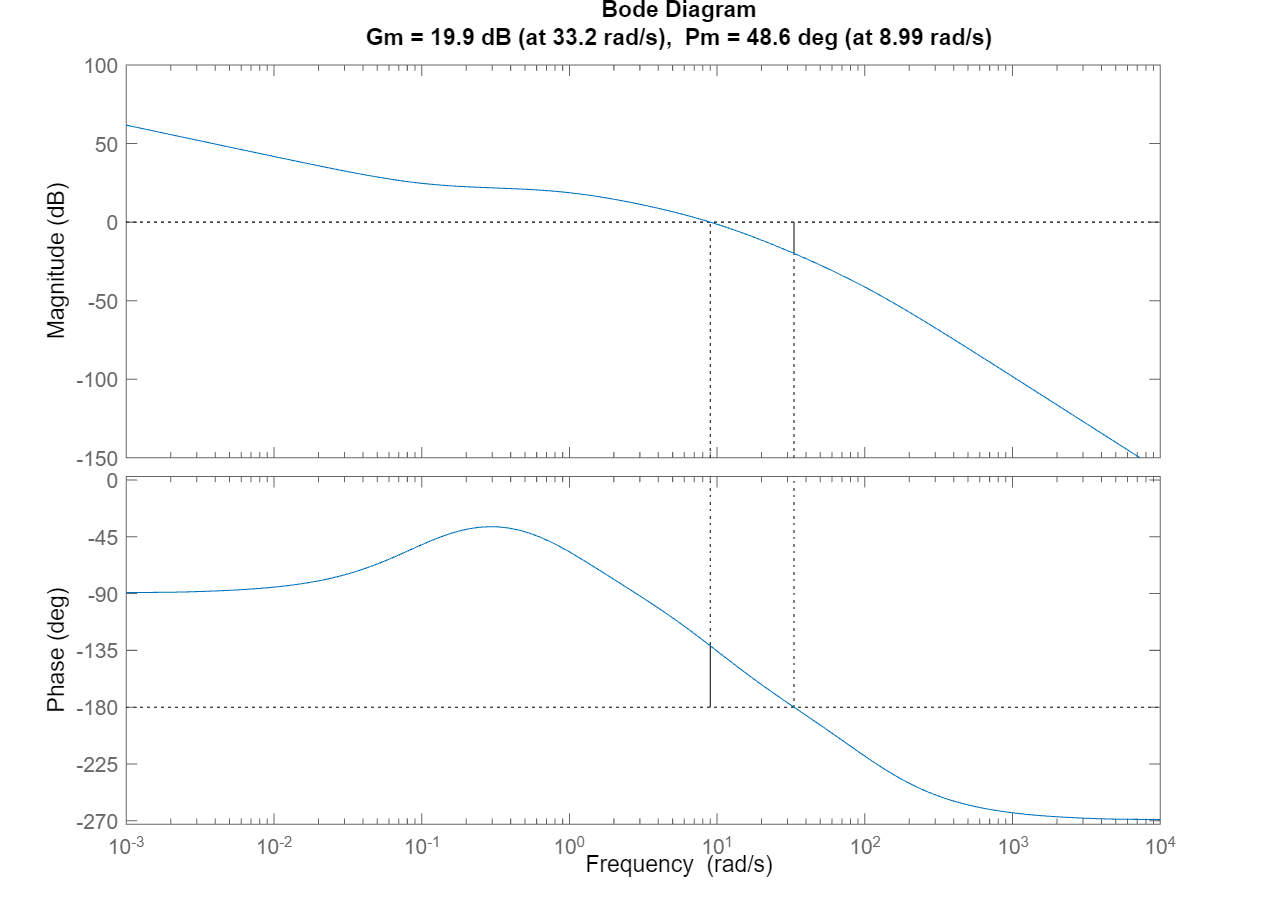

margin(G1)

Temos que MF=48.6º em w=8.99 rad/s e, para obtermos margem de fase nula, precisamos adicionar um atraso em nossa função G1, tal que na frequência de cruzamento de ganho, tenhamos o valor de ângulo de -180º. Para que isso ocorra:


$$d<\frac{\left(\pi \mathrm{MF}\right)}{180\omega }$$


Onde: 

- d é o delay que deve ser adicionado;

- MF é a margem de fase;

- w é a frequência em que ela ocorre.

Assim, temos aproximadamente:


$$d<\frac{\left(\pi 48\ldotp 6\right)}{180\ldotp \;8\ldotp 99}$$



$$d<0\ldotp 0943$$


Portanto, para que tenhamos margem de fase nula, é preciso adicionar um valor de delay menor que 0.0943, aproximadamente.

Plotando o gráfico de Bode com o atraso e verificando a MG e a MF:

G1_atrasada = G1;
G1_atrasada.InputDelay=0.0943

G1_atrasada =
 
                           1.222e04 s + 1222
  exp(-0.0943*s) * ---------------------------------
                   s^4 + 111 s^3 + 1110 s^2 + 1000 s
 
Continuous-time transfer function.
Model Properties


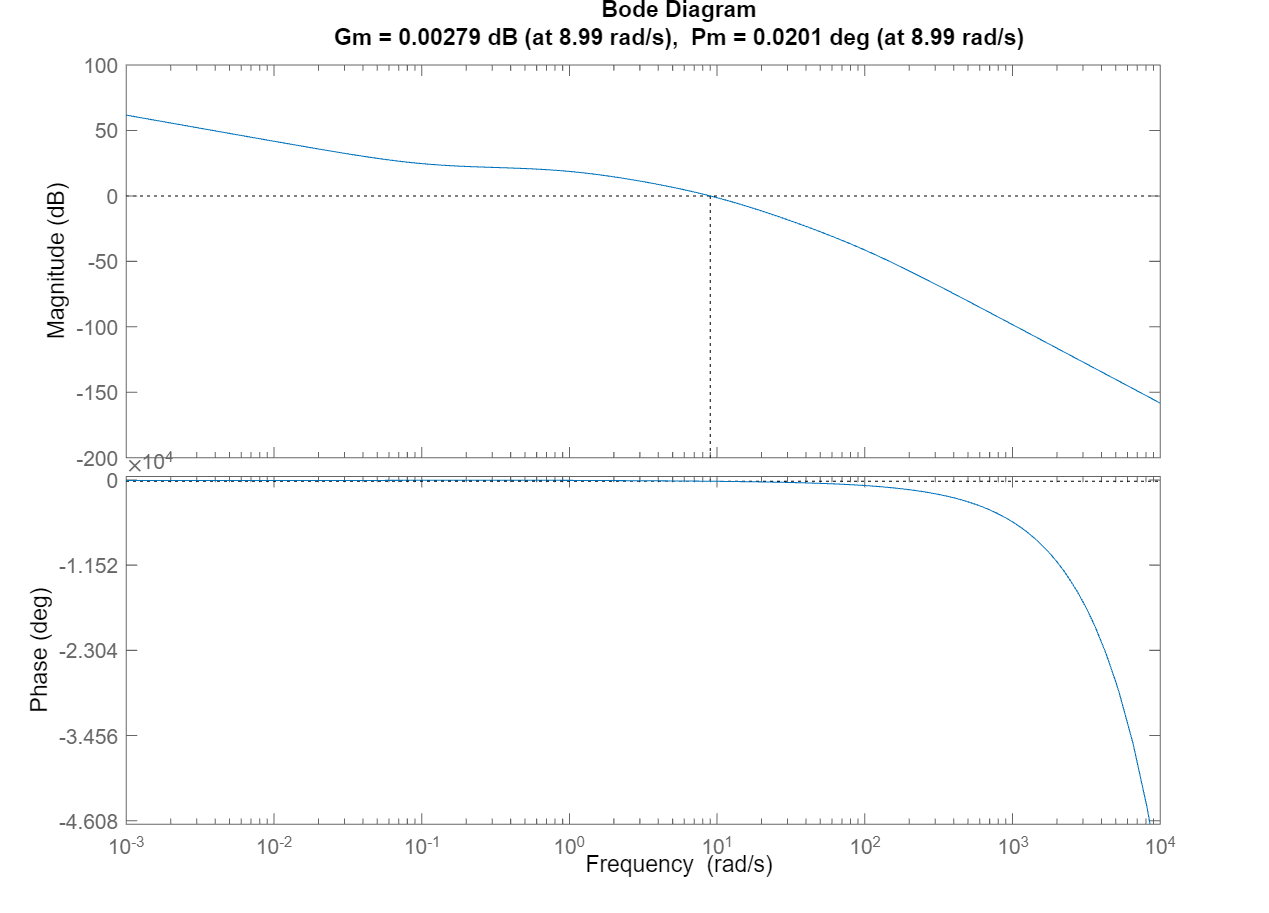

margin(G1_atrasada);

Fazendo um gráfico sobre o outro:

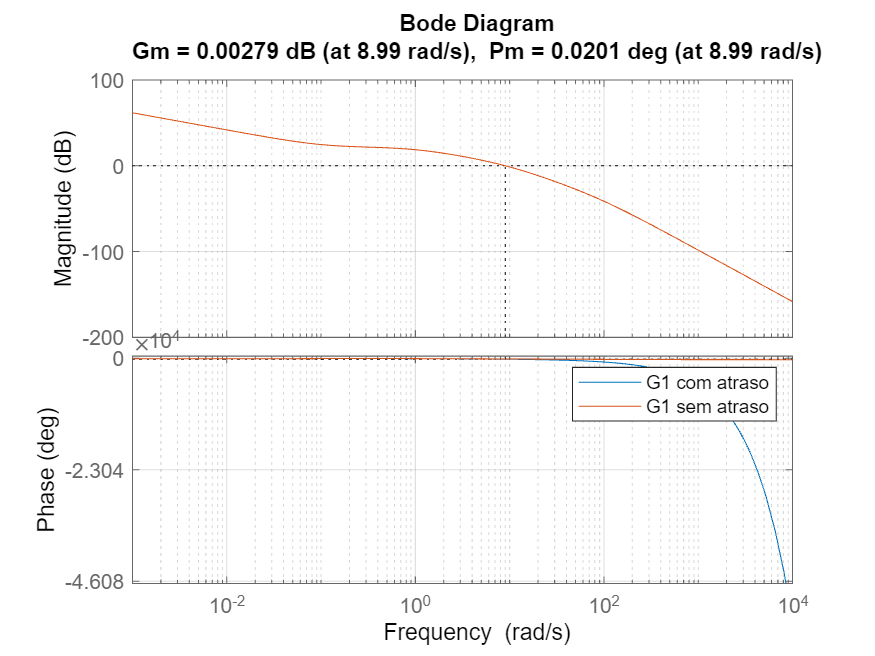

figure;
margin(G1_atrasada);
hold on;

bode(G1);
legend('G1 com atraso', 'G1 sem atraso');
grid on;

Com isso, podemos provar que de fato atingimos uma nova margem de fase aproximadamente nula com a aplicação do atraso. A margem de ganho permanece a mesma.